# Image Data Types

## Introduction

All images are stored as arrays of numbers. However, because medical images are acquired with specialized equipment, the range of possible intensity values in the data often does not align with standard data types used to store variables. Being aware of the range of values in your data and the data type used to store the images will help you properly view your images.

## Viewing Medical Images

Let's revisit the X-ray image of the back. It is stored as a 16-bit unsigned integer array (uint16). The intensity values for this data type range from 0 to 65,535. Small values will appear dark, and larger values bright. Try viewing the image with the `imshow` function. 

Adding a colorbar can help you identify the minimum and maximum values of the data type and compare that to your data range.

% Load the DICOM file
backXray = medicalImage("back view01.dcm")

backXray =   medicalImage with properties:

          Pixels: [2971×1575 uint16]
        Colormap: []
    SpatialUnits: "mm"
       FrameTime: []
       NumFrames: 1
    PixelSpacing: [0.1390 0.1390]
        Modality: 'CR'
    WindowCenter: 2048
     WindowWidth: 4096


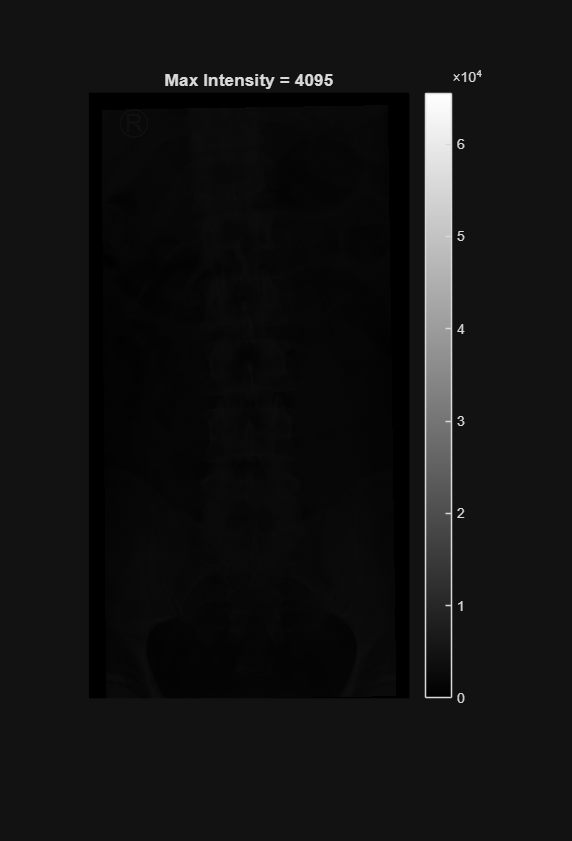

% Extract the image
img = extractFrame(backXray,1);
maxVal = max(img, [], "all");
% View using imshow
figure
imshow(img)
title("Max Intensity = " + maxVal)
colorbar

The image appears completely dark because the largest intensity value in the image is 4095, or about 6% of the full intensity range.

### Adjust the Display Scale

Adjust the display range to view the image. You do this using a second input argument to the `imshow` function, as described below:

- `imshow(img,[])` - Use the minimum and maximum values in the image as the display limits. This is a quick and fast way to view the data.

- `imshow(img,[low high])` - Manually specifcy the display limits. This is typically done to improve the visibility of a specific structure in the image.

Adding a colorbar to the image is a good way to communicate the display range to others.

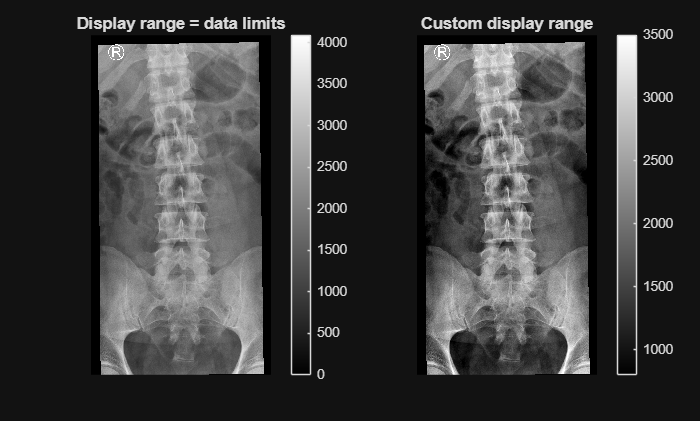

% Create a tiled layout to view the images side-by-side
figure
tiledlayout(1,2)
nexttile

% Approach 1: automatically use the minimum and maximum values in the image
imshow(img, [])
title("Display range = data limits")
colorbar

% Approach 3: manually set a custom display range 
nexttile
imshow(img, [800 3500])
title("Custom display range")
colorbar

## Adjusting the Intensity Values

Adjusting the display range does not change any of the intensity values, only how bright they are when displayed. Adjusting the actual data is often necessary when working with large datasets or images from different machines. Modifying your image data to occupy the same range of values enables you to compare images.

While there are many types of adjustments you can make, here we focus on two of the most common:

- Linearly scaling the intensity values to use the full range of the data type.

- Converting between data types.

### Scaling the intensity values

The intensity values of the back X-ray are 0 - 4095, but the `uint16` data type has a range of 0 - 65,535. Use the `imadjust` function to adjust the intensity values to use the full range of the `uint16` data type.

imgAdj = imadjust(img);

You can then view the adjusted image using `imshow` without needed the second input argument. The colorbar shows that the image is now using the full data range of the `uint16` data type.

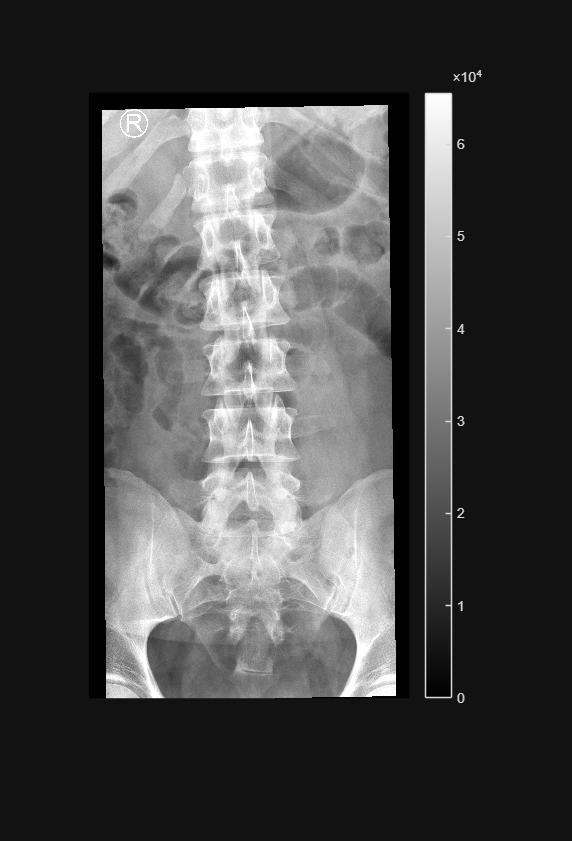

figure
imshow(imgAdj)
colorbar

### Converting to Different Data Types

Depending on the modality and specific equipment used, your images may be stored in a variety of data types. Your analysis may require converting data types to make all your images consistent. Additionally, it is best to convert your images to double precision when performing arithmetic operations on your data to have the highest precision and avoid errors.

There are several functions to help you convert data types. 

- [`im2uint8`](https://www.mathworks.com/help/images/ref/im2uint8.html) - convert to 8-bit unsigned integers (0 - 255)

- [`im2uint16`](https://www.mathworks.com/help/images/ref/im2uint16.html) - convert to 16-bit unsigned integers (0 - 65535)

- [`im2int16`](https://www.mathworks.com/help/images/ref/im2int16.html) - convert to 16-bit signed integers (-32768 - 32767)

- [`im2single`](https://www.mathworks.com/help/images/ref/im2single.html) - convert to single precision (32-bit) and rescales values to the range [0, 1]

- [`im2double`](https://www.mathworks.com/help/matlab/ref/im2double.html) - converts to double precision (64-bit) and rescales values to the range [0, 1]

Both the original image and the contrast-adjusted image have data type `uint16`. The code below converts both images to double precision and displays them. Notice that the range of values is now [0, 1]. However, the conversion maintains the relative intensity before and after the conversion. So, the original data converted to double precision still appears dark.

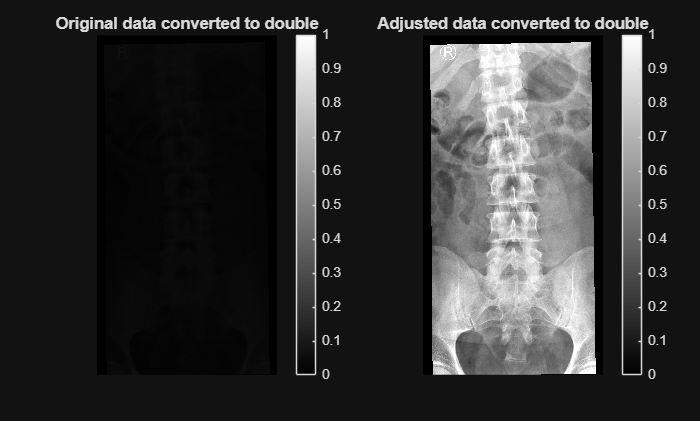

imgD = im2double(img);
imgDadj = im2double(imgAdj);

% Create a tiled layout to view the images side-by-side
figure
tiledlayout(1,2)
nexttile

imshow(imgD)
title("Original data converted to double")
colorbar

nexttile
imshow(imgDadj)
title("Adjusted data converted to double")
colorbar

## Further Resources

There are many possible contrast adjustments and operations you might perform on your images. Once you have your data in MATLAB and properly scaled, you work with medical images just like other images. If you haven't already, enroll [Introduction to Image Processing](https://www.coursera.org/learn/introduction-image-processing) to learn more about common image operations.

*Copyright 2024 The MathWorks, Inc.*